**Initialize:**

n = 1201;                   % Number of locations to evaluate bridge failure
L = 1200;                   % Length of bridge
x = linspace(0, L, 1201);      % Define x coordinate
% P_each = [-66.7 -66.7 -66.7 -66.7 -90 -90]; % Set train load as 6 point loads applied via the wheels
P_each = [-66.7 -66.7 -66.7 -66.7 -66.7 -66.7]; % Load Case 1
self = 0; % Self Weight

**Load Case 2:**

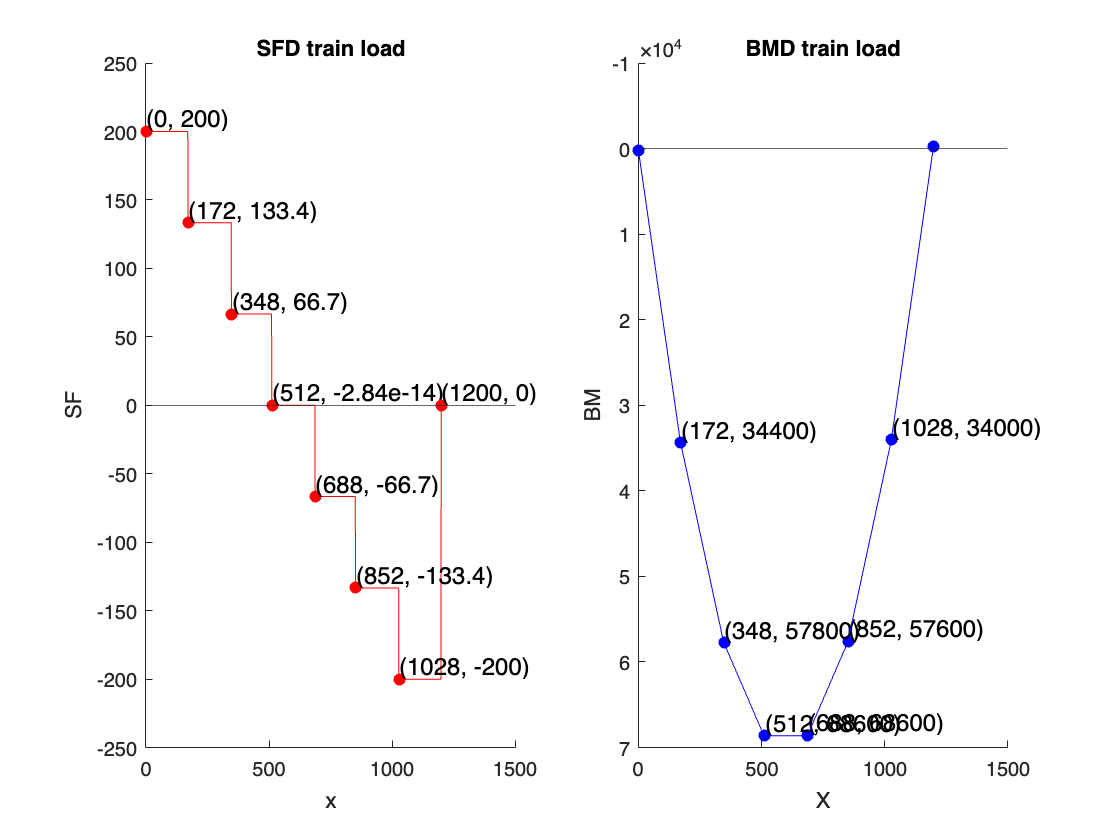

x0 = 172; % First Point Position
SFD_TL1 = zeros(1,n);
total_loads = zeros(1, n);
    x_load = [x0,x0+176,x0+340,x0+516,x0+680,x0+856];
    totalB = 0;
    total_load = 0;

    % Support Reactions
    for i = 1:6
        totalB = totalB + (x_load(1,i)*P_each(1,i));
        total_load = total_load + P_each(1,i);
    end
    total_load = total_load - self*L;
    Sup_B = -(totalB - (self*L*L)/2)/L;
    Sup_A = -total_load - Sup_B;
    SFD_TL1(1,1) = Sup_A;
    SFD_TL1(1,L) = Sup_B;

% Creating Points for SFD
for i = 1:6
    SFD_TL1(1,x_load(1,i)) = SFD_TL1(1,x_load(1,i)) + P_each(1,i);
end

for c = 2:L-1
    SFD_TL1(1,c) = SFD_TL1(1,c) + SFD_TL1(1,c-1)-self;
end

SFD_TL1(1,L) = SFD_TL1(1,L-1) + Sup_B;

%SFD 
subplot(1,2,1)
hold on
plot(x, SFD_TL1,'red') % plot the SF_matrix against x
% Add Data Points
shearLabel = zeros(1,6);
for i = 1:6
scatter(x_load(i), SFD_TL1(x_load(i)), "filled", "red")
SFD_str = num2str(abs(SFD_TL1(x_load(i))));
if str2num(SFD_str(1)) == 1
shearLabel(i)=round(SFD_TL1(x_load(i)),4,"significant");
else
shearLabel(i)=round(SFD_TL1(x_load(i)),3,"significant");
end
end

for i = 1:6
text(x_load(i), SFD_TL1(x_load(i)), "("+num2str(x_load(i)) +", " +shearLabel(i) +")", 'VerticalAlignment','bottom','FontSize',12);
end

scatter(1200,SFD_TL1(1200),  "filled", "red")
text(1200, SFD_TL1(1200), "("+num2str(1200) +", " + 0 +")", 'VerticalAlignment','bottom','FontSize',12);

SFD_str = num2str(abs(SFD_TL1(1)));
if str2num(SFD_str(1)) == 1
    shearLabel(1)=round(SFD_TL1(1),4,"significant");
else
    shearLabel(1)=round(SFD_TL1(1),3,"significant");
end
scatter(1,SFD_TL1(1), "filled", "red")
text(0, SFD_TL1(1), "("+num2str(0) +", " + shearLabel(1) +")", 'VerticalAlignment','bottom','FontSize',12);
yline(0)

%Labels
xlabel('x')
ylabel('SF')
title('SFD train load')
hold off

%BMD
BMD_TL1 = cumsum(SFD_TL1);
BMD_TL1(n) = 0;

%Add Data Labels
subplot(1,2,2)
hold on
BMDLabel = zeros(1,6);
for i = 1:6
scatter(x_load(i), BMD_TL1(x_load(i)), "filled", "blue")
BMD_str = num2str(abs(BMD_TL1(x_load(i))));
if str2num(BMD_str(1)) == 1
BMDLabel(i)=round(BMD_TL1(x_load(i)),4,"significant");
else
BMDLabel(i)=round(BMD_TL1(x_load(i)),3,"significant");
end
end
for i = 1:6
text(x_load(i), BMD_TL1(x_load(i)), "("+num2str(x_load(i)) +", " +BMDLabel(i) +")", 'VerticalAlignment','bottom','FontSize',12);
end
scatter(1, BMD_TL1(1), "filled", "blue")
scatter(1200, BMD_TL1(1200), "filled", "blue")
yline(0)
plot(x, BMD_TL1,'blue') % plot the BM_matrix against x
xlabel('X')
ylabel('BM')
title('BMD train load')
set(gca, 'YDir', 'reverse')
hold off

**SFD and BMD Envelope:**

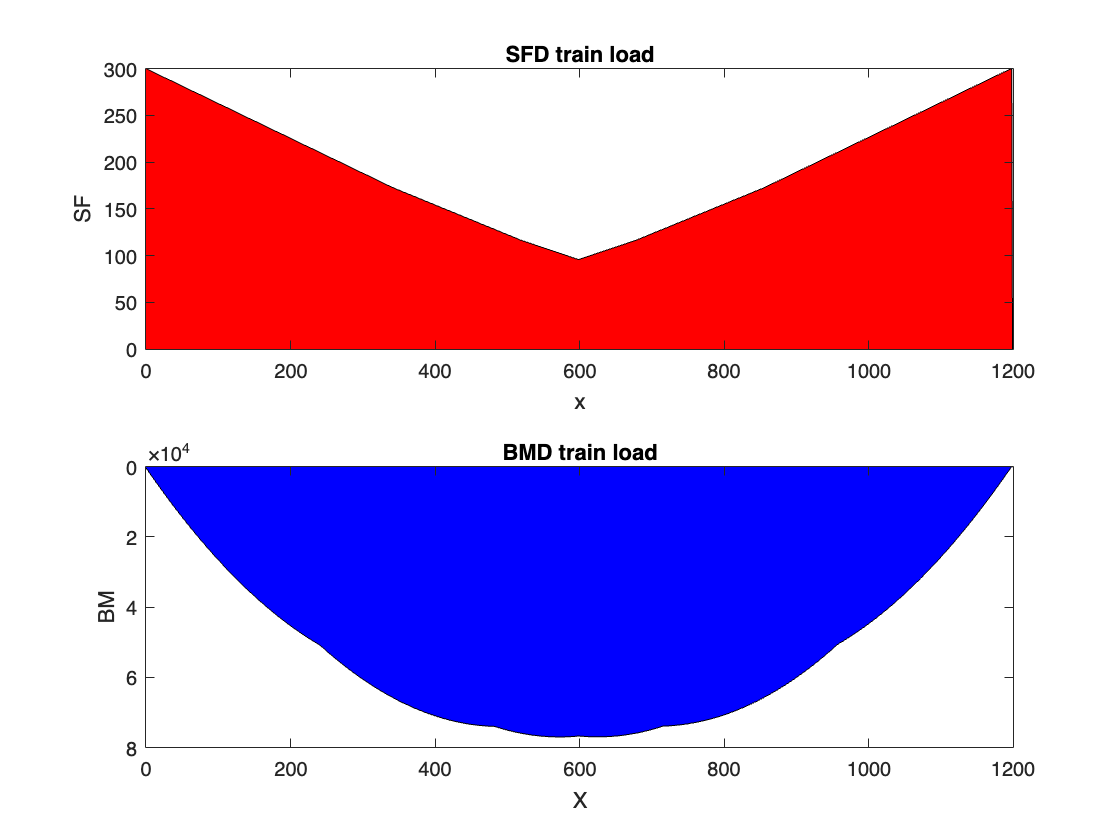

P_each = [-66.7 -66.7 -66.7 -66.7 -90 -90]; % Set train load as 6 point loads applied via the wheels
self = 0; % Self Weight
n = 1201;
L = 1200;
x = linspace(0, L, n);

SFD_TL_Total = zeros(2054, n);
BMD_TL_Total = zeros(2054, n);
SFD_Env_TL = zeros(2,n);
BMD_Env_TL = zeros(2,n);

SFD_Env = zeros(1,n);
BMD_Env = zeros(1,n);
for q = 1:2
for k = -854:1199
    % Initiating List Sizes
    SFD_TL = zeros(1,n);
    BMD_TL = zeros(1,n);

    total_loads = zeros(1, n);
    x0 = k;
    x_load = [x0,x0+176,x0+340,x0+516,x0+680,x0+856];
    totalB = 0;
    total_load = 0;
    % Support Reactions
    for i = 1:6
        if x_load(1,i)>1 && x_load(1,i)<=1197
        totalB = totalB + (x_load(1,i)*P_each(1,i));
        total_load = total_load + P_each(1,i);
        end
    end

    total_load = total_load - self*L;
    Sup_B = -(totalB - (self*L*L)/2)/L;
    Sup_A = -total_load - Sup_B;
    SFD_TL(1,1) = Sup_A;
    SFD_TL(1,L) = Sup_B;

for i = 1:6
    if 1<x_load(1,i) && x_load(1,i)<=1197
        SFD_TL(1,x_load(1,i)) = SFD_TL(1,x_load(1,i)) + P_each(1,i);
    end
end

for p = 2:L-1
    SFD_TL(1,p) = SFD_TL(1,p) + SFD_TL(1,p-1)-self;
end
    SFD_TL(1,L) = SFD_TL(1,L-1) + Sup_B;
    BMD_TL = cumsum(SFD_TL);
    BMD_TL(n) = 0;

    SFD_TL_Total(k+855,:) = SFD_TL;
    BMD_TL_Total(k+855,:) = BMD_TL;
end
SFD_Env = zeros(1,L);
 for i = 1:n
    if max(SFD_TL_Total(:,i)) > -(min(SFD_TL_Total(:,i)))
     SFD_Env_TL(q,i) = max(SFD_TL_Total(:,i));
    else
     SFD_Env_TL(q,i) = min(SFD_TL_Total(:,i));
    end
    BMD_Env_TL(q,i) = max(BMD_TL_Total(:, i));
 end
 P_each = [-90 -90 -66.7 -66.7 -66.7 -66.7];
end
 
for i = 1:n
    if max(SFD_Env_TL(:,i)) > -(min(SFD_Env_TL(:,i)))
     SFD_Env(1,i) = max(SFD_Env_TL(:,i));
    else
     SFD_Env(1,i) = abs(min(SFD_Env_TL(:,i)));
    end
     BMD_Env(1,i) = max(BMD_Env_TL(:, i));
 end
subplot(2,1,1)
plot(x, SFD_Env, "red")
area(x, SFD_Env, 'FaceColor',"r")
xlabel('x')
ylabel('SF')
title('SFD train load')

subplot(2,1,2)
plot(x, BMD_Env,'blue') % plot the BM_matrix against x
area(x, BMD_Env, 'FaceColor',"b")
xlabel('X')
ylabel('BM')
title('BMD train load')
set(gca, 'YDir', 'reverse')

**Cross-Sections:**

%% 2. Define Cross-Section Inputs & Calculate Cross-Section Properties
% Cross Section Inputs
xc = [0 200 325 525 725 850 1200]; % Location, x, of cross-section change
ybot = [41.4 41.4 41.4 41.4 41.4 41.4 41.4];
ytop = [34.8 34.8 34.8 34.8 34.8 34.8 34.8];
I = [418000 418000 418000 418000 418000 418000 418000];
QCent = [6193 6193 6193 6193 6193 6193 6193];
QGlue = [4344 4344 4344 4344 4344 4344 4344];

Sig_web_b = [29.43 29.43 29.43 29.43 29.43 29.43 29.43];
Sig_flange_b = [4.067 4.067 4.067 4.067 4.067 4.067 4.067];
Sig_side_flange_b = [23.49 23.49 23.49 23.49 23.49 23.49 23.49];
% Sig_shear_b = [22.10 18.12 13.8 13.8 18.12 22.10 22.10];
Sig_shear_b = [5.08 5.08 5.08 5.08 5.08 5.08 5.08];
gtb = [5 5 5 5 5 5 5];
wt = [1.27 1.27 1.27 1.27 1.27 1.27 1.27];

% Interpolate values across every mm of bridge
ybot = interp1(xc, ybot, x);
ytop = interp1(xc, ytop, x);
I = interp1(xc, I, x);
Qcent = interp1(xc, QCent, x);
Qglue = interp1(xc, QGlue, x);
Sig_web_b = interp1(xc, Sig_web_b, x);
Sig_flange_b = interp1(xc, Sig_flange_b, x);
Sig_side_flange_b = interp1(xc, Sig_side_flange_b, x, "previous");
Sig_shear_b = interp1(xc, Sig_shear_b, x, "previous");
wt = interp1(xc, wt, x);
gtb = interp1(xc, gtb, x);


bcent = 2 * wt;
bglue = (2 * gtb); % + bcent % without bcent assumes imperfect glue tab

% Calculate cross-section properties


**Material Properties**

%% 3. Define Material Properties
SigT = 30;  % Tensile strength
SigC = 6;   % Compressive strength
E = 4000;   % Young's Modulus
TauU = 4;   % Shear strength, matboard
TauG = 2;   % Shear strength, glue
mu = 0.2;   % Poisson's ratio

**Failure Methods:**

m = max(BMD_TL1)     

m = 6.8634e+04

% Top Compression Stress
s_top = (m*ytop)/I

s_top = 5.7141

% Bottom Tension Stress
s_bot = (m*ybot)/I

s_bot = 6.7978

% Compression FOS
FOS_C = SigC/s_top

FOS_C = 1.0500

% Tension FOS
FOS_T = SigT/s_bot

FOS_T = 4.4132

% Shear Failure (Matboard, Glue)
[ V_Buck ] = VfailBuck(x, Sig_shear_b, I, Qcent, wt)

V_Buck =   435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544  435.4544


[ V_MatFail, V_GlueFail ] = Vfail(Qcent, Qglue, bcent, bglue, I, TauU, TauG )

V_MatFail =   685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549  685.7549


V_GlueFail = 1.0e+03 *

    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245    1.9245


[ M_MatC ] = MfailMatC( x, ybot, ytop, I, SigC, BMD_TL1 )

M_MatC = 1.0e+04 *

    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069    7.2069


[ M_MatT ] = MfailMatT( x, ybot, ytop, I, SigT, BMD_TL1)

M_MatT = 1.0e+05 *

    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290    3.0290


[wbuck, flbuck, side] = BucklingFail(x, ytop, Sig_web_b, Sig_flange_b, I, Sig_side_flange_b)

wbuck = 1.0e+05 *

    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350    3.5350


flbuck = 1.0e+04 *

    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851    4.8851


side =       282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150      282150


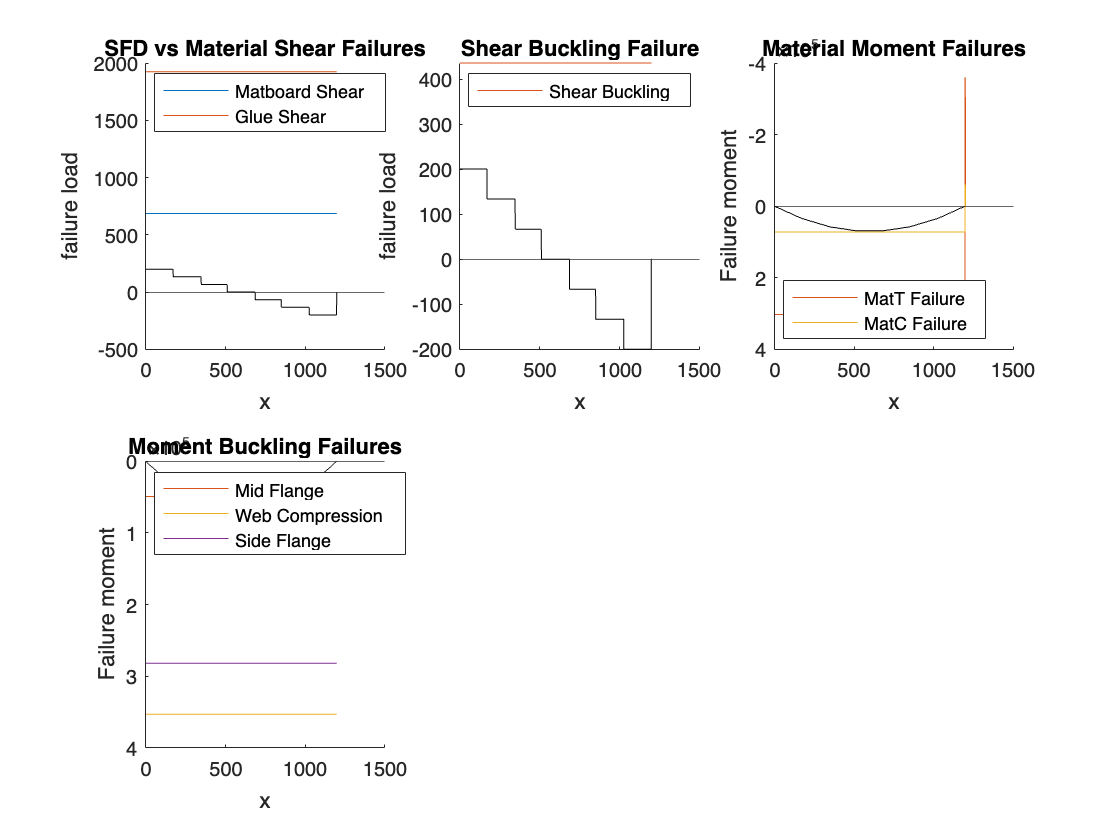

Visualize(x, BMD_TL1, SFD_TL1, V_MatFail, V_GlueFail, V_Buck, M_MatC, M_MatT, wbuck, flbuck, side)

[FOSC,FOST,FOSS,FOSSB,FOSCBW,FOSCBF,FOSCBFS,FOSGLUE] = FOS(x, BMD_TL1, SFD_TL1, V_MatFail, V_GlueFail, V_Buck, M_MatC, M_MatT, wbuck, flbuck, side)

FOSC = 1.0500

FOST = 4.4132

FOSS = 3.4271

FOSSB = 2.1762

FOSCBW = 5.1505

FOSCBF = 0.7118

FOSCBFS = 4.1109

FOSGLUE = 9.6177

**Functions:**

function [ V_MatFail, V_GlueFail ] = Vfail( Qcent, Qglue, bcent, ...
    bglue, I, TauU, TauG )
% Calculates shear forces at every value of x that would
% cause a matboard shear failure and a glue shear failure
% Input: Sectional Properties (list of 1-D arrays), 
% TauU (scalar material property)
% Output: V_MatFail, V_GlueFail, both 1-D arrays of length n
V_MatFail = zeros(1, length(Qcent));
V_GlueFail = zeros(1, length(Qglue));

for i = 1:length(Qcent)
    V_MatFail(i) = TauU * I(i) * bcent(i) / Qcent(i);
    V_GlueFail(i) = TauG * I(i) * bglue(i) / Qglue(i);

end
end

function [ V_Buck ] = VfailBuck ( x, Sig_V_buck, I, q, wt)
% Calculates shear forces at every value of x that would 
% cause a shear buckling failure in the web
% Input: Sectional Properties (list of 1-D arrays), E, mu (material property)
% Output: V_Buck a 1-D array of length n

V_Buck = zeros(1, length(x));

for i = 1:length(x)
    V_Buck(i) = Sig_V_buck(i) * I(i) * wt(i)/q(i);
end
end

function [wbuck, flbuck, sflbuck] = BucklingFail(x, ytop, web, flange, I, side)
wbuck = zeros(1, length(x));
flbuck = zeros(1, length(x));
sflbuck = zeros(1, length(x));

for i = 1:length(x)
    wbuck(i) = web(i) * I(i)/ytop(i);
    flbuck(i) = flange(i)* I(i)/ytop(i);
    sflbuck(i) = side(i) * I(i)/ytop(i);
end 

end
function [ M_MatT ] = MfailMatT( x, ybot, ytop, I, SigT, BMD )
% Calculates bending moments at every value of x that would 
% cause a matboard tension failure
% Input: Sectional Properties (list of 1-D arrays), 
% SigT (material property), BMD (1-D array)
% Output: M_MatT (1-D array of length n)
M_MatT = zeros(1, length(x));

for i = 1:length(x)
    if BMD(i) > 0 % If moment is (+), tension failure will be at the bottom
        M_MatT(i) = SigT * I(i) / ybot(i);
    elseif BMD(i) < 0 % If moment is (-), tension failure will be at the top
        M_MatT(i) = -SigT * I(i) / ytop(i);
    end
end
end

function [ M_MatC ] = MfailMatC( x, ybot, ytop, I, SigC, BMD )
% Calculates bending moments at every value of x that would 
% cause a matboard compression failure
% Input: Sectional Properties (list of 1-D arrays), 
% SigC (material property), BMD (1-D array)
% Output: M_MatT (1-D array of length n)
M_MatC = zeros(1, length(x));

for i = 1:length(x)
    if BMD(i) > 0 % If moment is (+), compression failure will be at the top
        M_MatC(i) = SigC * I(i) / ytop(i);
    elseif BMD(i) < 0 
        % If moment is (-), compression failure will be at the bottom
        M_MatC(i) = -SigC * I(i) / ybot(i);
    end
end
end

function [FOSC,FOST,FOSS,FOSSB,FOSCBW,FOSCBF,FOSCBFS,FOSGLUE] = FOS(x, BMD_Env, SFD_Env, V_MatFail, V_GlueFail, V_Buck, M_MatC, M_MatT, web, flange, side)
    FOSc = zeros(1,length(x)-1);
    FOSt = zeros(1,length(x)-1);
    FOSs = zeros(1,length(x)-1);
    FOSsb = zeros(1,length(x)-1);
    FOScbw = zeros(1,length(x)-1);
    FOScbf = zeros(1,length(x)-1);
    FOScbfs = zeros(1,length(x)-1);
    FOSglue = zeros(1,length(x)-1);

for i = 1:length(x)-1
    FOSc(i) = abs(M_MatC(i))/abs(BMD_Env(i));
    FOSt(i) = abs(M_MatT(i))/abs(BMD_Env(i));
    FOSs(i) = V_MatFail(i)/abs(SFD_Env(i));
    FOSsb(i) = V_Buck(i)/abs(SFD_Env(i));
    FOScbw(i) = web(i)/abs(BMD_Env(i));
    FOScbf(i) = flange(i)/abs(BMD_Env(i));
    FOScbfs(i) = side(i)/abs(BMD_Env(i));
    FOSglue(i) = V_GlueFail(i)/abs(SFD_Env(i));
end

FOSC = min(FOSc);
FOST = min(FOSt);
FOSS = min(FOSs);
FOSSB = min(FOSsb);
FOSCBW = min(FOScbw);
FOSCBF = min(FOScbf);
FOSCBFS = min(FOScbfs);
FOSGLUE = min(FOSglue);

end

function [] = Visualize(x, BMD_Env, SFD_Env, V_MatFail, V_GlueFail, V_Buck, M_MatC, M_MatT, web, flange, side)
    subplot(2, 3, [1,1,1])
    hold on
    title("SFD vs Material Shear Failures")
    xlabel('x')
    ylabel('failure load')
    plot(x, V_MatFail)
    plot(x, V_GlueFail)
    plot(x, SFD_Env, 'k')
    yline(0)
    legend('Matboard Shear', 'Glue Shear', '', 'Location', 'northwest')
    hold off

    subplot(2, 3, [2,2])
    hold on
    title("Shear Buckling Failure")
    xlabel('x')
    ylabel('failure load')
    plot(x, SFD_Env, 'k')
    plot(x, V_Buck)
    yline(0)
    legend('', 'Shear Buckling', 'Location', 'northwest')
    hold off

    subplot(2, 3, [3,3,3])
    hold on
    title("Material Moment Failures")
    xlabel('x')
    ylabel('Failure moment')
    set(gca, 'YDir', 'reverse')
    plot(x, BMD_Env, 'k')
    plot(x, M_MatT)
    plot(x, M_MatC)
    yline(0)
    legend('', 'MatT Failure', 'MatC Failure', 'Location', 'southwest')
    hold off

    subplot(2, 3, [4,4,4,4])
    hold on
    title("Moment Buckling Failures")
    xlabel('x')
    ylabel('Failure moment')
    set(gca, 'YDir', 'reverse')
    plot(x, BMD_Env, 'k')
    plot(x, flange)
    plot(x, web)
    plot(x, side)
    yline(0)
    legend('', 'Mid Flange', 'Web Compression', "Side Flange", 'Location', ...
        'northwest')
    hold off
end